# Laboratorio 3 Robótica: Modelo diferencial de primer orden

## Universidad Nacional de Colombia

## Alejandro Ojeda Olarte, Brayan Calderon, Mateo Rodriguez

## Asignacion de Ruta

Teniendo en cuenta el robot asignado y los resultados obtenidos en el Lab 1  Análisis de las características de un Robot Industrial y Modelo geométrico directo. Resuelva los siguientes enunciados.

#### 1.Se asigna un plano en el que debe crear una ruta y simular el movimiento de seguimiento del robot. Deberá presentarla simulación de al menos una de las rutas propuestas, pueden crear y simular otras rutas y/o otros planos.

Para el grupo 1, nos toca el vector $\left\lbrack \begin{array}{ccc}
1 & 0 & 1
\end{array}\right\rbrack$. Se escoge la segunda figura de las opciones, y dado que el alcance del robot es 500mm, la dimensión L será 200mm. Se define una longitud del tramo largo recto de 150mm, un ancho de 150mm y un radio para el semicírculo de 50mm. La trayectoria se grafica a continuación.

resolution=60;
radius=0.050; %In mm
L_side=0.150; %in mm

curve_y=linspace(-0.050,0.050,resolution);
curve_x=sqrt(-curve_y.^2 + radius^2);
curve_z=-curve_x+(L_side*cos(45)*0.5)+(radius*0.5);

side_x=linspace(-(L_side*cos(45)),0,resolution);
side_1y=ones(1,length(side_x))*-radius;
side_2y=ones(1,length(side_x))*+radius;
sides_z=-side_x+(L_side*cos(45)*0.5)+(radius*0.5);

cross_x=ones(1,length(side_x))*min(side_x);
cross_y=linspace(-radius,radius,resolution);
cross_z=ones(1,length(side_x))*max(sides_z);

trayectoria_Final_y = [curve_y, side_2y, fliplr(cross_y), side_1y]

trayectoria_Final_y =    -0.0500   -0.0483   -0.0466   -0.0449   -0.0432   -0.0415   -0.0398   -0.0381   -0.0364   -0.0347   -0.0331   -0.0314   -0.0297   -0.0280   -0.0263   -0.0246   -0.0229   -0.0212   -0.0195   -0.0178   -0.0161   -0.0144   -0.0127   -0.0110   -0.0093   -0.0076   -0.0059   -0.0042   -0.0025   -0.0008    0.0008    0.0025    0.0042    0.0059    0.0076    0.0093    0.0110    0.0127    0.0144    0.0161    0.0178    0.0195    0.0212    0.0229    0.0246    0.0263    0.0280    0.0297    0.0314    0.0331


trayectoria_Final_x = [curve_x, side_x, cross_x, side_x]

trayectoria_Final_x =          0    0.0129    0.0181    0.0220    0.0251    0.0279    0.0302    0.0323    0.0342    0.0360    0.0375    0.0389    0.0403    0.0414    0.0425    0.0435    0.0445    0.0453    0.0460    0.0467    0.0473    0.0479    0.0484    0.0488    0.0491    0.0494    0.0496    0.0498    0.0499    0.0500    0.0500    0.0499    0.0498    0.0496    0.0494    0.0491    0.0488    0.0484    0.0479    0.0473    0.0467    0.0460    0.0453    0.0445    0.0435    0.0425    0.0414    0.0403    0.0389    0.0375


trayectoria_Final_z = [curve_z, sides_z, cross_z, sides_z]

trayectoria_Final_z =     0.0644    0.0515    0.0463    0.0424    0.0393    0.0365    0.0342    0.0321    0.0302    0.0284    0.0269    0.0255    0.0241    0.0230    0.0219    0.0209    0.0199    0.0191    0.0184    0.0177    0.0171    0.0165    0.0160    0.0156    0.0153    0.0150    0.0148    0.0146    0.0145    0.0144    0.0144    0.0145    0.0146    0.0148    0.0150    0.0153    0.0156    0.0160    0.0165    0.0171    0.0177    0.0184    0.0191    0.0199    0.0209    0.0219    0.0230    0.0241    0.0255    0.0269



% plot3(curve_x,curve_y,curve_z)
% hold on
% plot3(side_x,side_1y,sides_z)
% plot3(side_x,side_2y,sides_z)
% plot3(cross_x,cross_y,cross_z)
% hold off
c=2.1

c = 2.1000

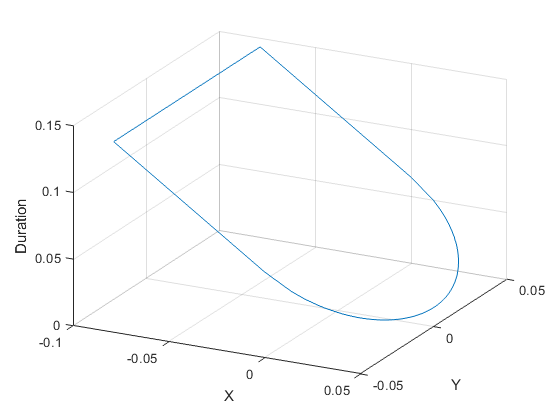

plot3(trayectoria_Final_x,trayectoria_Final_y, ...
    trayectoria_Final_z)

xlabel('X')
ylabel('Y')
zlabel('Duration')
grid on

view([27 28])

L(1) = Link([0 0.152 0 0],'modified');
L(2) = Link([0 0.120 0 pi/2 0 pi/2],'modified');
L(3) = Link([0 0 0.244 0],'modified');
L(4) = Link([0 -0.010 0.213 0 0 -pi/2],'modified');
L(5) = Link([0 0.083 0 -pi/2],'modified');
L(6) = Link([0 0.082 0 pi/2],'modified');
UR3 = SerialLink(L,'name','Universal Robot UR3')

 
UR3 = 
 
Universal Robot UR3 (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.152|          0|          0|          0|
|  2|         q2|       0.12|          0|      1.571|      1.571|
|  3|         q3|          0|      0.244|          0|          0|
|  4|         q4|      -0.01|      0.213|          0|     -1.571|
|  5|         q5|      0.083|          0|     -1.571|          0|
|  6|         q6|      0.082|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              



syms q0 q1 q2 q3 q4 q5
T01 = L(1).A(q0);
T12 = L(2).A(q1);
T23 = L(3).A(q2);
T34 = L(4).A(q3);
T45 = L(5).A(q4);
T56 = L(6).A(q5);
T06 = T01*T12*T23*T34*T45*T56;

%Matrices de rotacion
R01=T01( 1:3,1:3);
R12=T12( 1:3,1:3);
R23=T23( 1:3,1:3);
R34=T34( 1:3,1:3); 
R45=T45( 1:3,1:3);
R56=T56( 1:3,1:3);
%Vectores de posicion
P01=T01(1:3,4);
P12=T12(1:3,4);
P23=T23(1:3,4);
P34=T34(1:3,4);
P45=T45(1:3,4);
P56=T56(1:3,4);

%Base
e0=0;
v0p=0;
Te0p=0;

v00=e0 *v0p*[0;0;1];
w00=e0 *Te0p*[0;0;1];

%Limb 1
e1=0;%Es rotacional
syms d1p Te1p Te2p Te3p Te4p Te5p Te6p
v11=(1-e1)* R01 * (v00 + skew(w00)*P01 ) + e1*d1p;
w11= R01* w00 +(1-e1)*Te1p * [0;0;1];

v22=(1-e1)* R12 * (v11 + skew(w11)*P12 ) + e1*d1p;
w22= R12* w11 +(1-e1)*Te2p * [0;0;1];

v33=(1-e1)* R23 * (v22 + skew(w22)*P23 ) + e1*d1p;
w33= R23* w22 +(1-e1)*Te3p * [0;0;1];

v44=(1-e1)* R34 * (v33 + skew(w33)*P34 ) + e1*d1p;
w44= R34* w33 +(1-e1)*Te4p * [0;0;1];

v55=(1-e1)* R45 * (v44 + skew(w44)*P45 ) + e1*d1p;
w55= R45* w44 +(1-e1)*Te5p * [0;0;1];

v66=vpa(simplify((1-e1)* R56 * (v55 + skew(w55)*P56 ) + e1*d1p),3);
w66= vpa(simplify((R56* w55 +(1-e1)*Te6p * [0;0;1]),3),3);

## Modelo diferencial de primer orden

Considerando que para que el robot ejecute los movimientos, se desea establecer una relación entre las velocidades del efector final y las articulaciones.

#### 1. Con los valores numéricos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numericos, NO simbólico) en función de los ángulos de articulación.

Jacobiano = zeros(6,6)*q1

$$Jacobiano = \left(\begin{array}{cccccc} 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

Jacobiano(1,1)=(3*sin(q1 - q5))/50 + (213*sin(q2 - q5))/2000 + (83*sin(q2 + q3 + q5))/2000 + (3*cos(q1 + q2 + q3 + q4 - q5))/100 - (3*cos(q2 - q1 + q3 + q4 + q5))/100 - (83*sin(q2 + q3 - q5))/2000 + (23*sin(q2 + q3 + q4 + q5))/500 - (3*sin(q1 + q5))/50 - (213*sin(q2 + q5))/2000 - (3*cos(q2 - q1 + q3 + q4 - q5))/100 - (61*sin(q5))/250 + (23*sin(q2 + q3 + q4 - q5))/500 + (3*cos(q1 + q2 + q3 + q4 + q5))/100;
Jacobiano(1,2)=0.122*cos(q2+q3+q4+q5)+-0.0415*cos(q4+q5)+0.1065*cos(q3+q4-1.0*q5)+0.0*cos(q5)+0.1065*cos(q3+q4+q5)+0.122*cos(q2+q3+q4-1.0*q5)+-0.0415*cos(q4-1.0*q5);
Jacobiano(1,3)=-0.0415*cos(q4+q5)+0.1065*cos(q3+q4-1.0*q5)+0.0*cos(q5)+0.1065*cos(q3+q4+q5)+-0.0415*cos(q4-1.0*q5);
Jacobiano(1,4)=-0.0415*cos(q4+q5)+0.0*cos(q5)+-0.0415*cos(q4-1.0*q5);
Jacobiano(1,5)=0.082*cos(q5);

Jacobiano(2,1)=0.0*sin(q4-1.0*q5)+-0.0+-0.0*cos(q2+q3+q4+q5)+0.06*sin(q1+q2+q3+q4)+0.0*sin(q2+q3+q4+q5)+0.0*cos(q2+q3)+0.0*cos(q1+q5)+0.0*cos(q2+q5)+-0.0*sin(q1+q2+q3+q4-1.0*q5)+-0.0*sin(q2-1.0*q1+q3+q4+q5)+0.0*sin(q3+q4)+-0.0*sin(q4+q5)+-0.0*cos(q2+q3-1.0*q5)+-0.0*sin(q3+q4-1.0*q5)+-0.0*cos(q1)+-0.0*cos(q2)+0.0*cos(q5)+-0.0*sin(q4)+0.0*sin(q5)+0.0*sin(q1+q2+q3+q4+q5)+-0.092*cos(q2+q3+q4)+-0.0*cos(q2+q3+q5)+0.0*sin(q2+q3+q4)+0.0*sin(q3+q4+q5)+0.0*cos(q2+q3+q4-1.0*q5)+-0.06*sin(q2-1.0*q1+q3+q4)+-0.0*sin(q2+q3+q4-1.0*q5)+0.0*cos(q1-1.0*q5)+0.0*cos(q2-1.0*q5)+0.0*sin(q2-1.0*q1+q3+q4-1.0*q5);
Jacobiano(2,2)=0.0*sin(q4-1.0*q5)+0.0*sin(q2+q3+q4+q5)+0.213*sin(q3+q4)+-0.0*sin(q4+q5)+-0.0*sin(q3+q4-1.0*q5)+-0.083*sin(q4)+0.0*sin(q5)+0.244*sin(q2+q3+q4)+0.0*sin(q3+q4+q5)+-0.0*sin(q2+q3+q4-1.0*q5);
Jacobiano(2,3)=0.0*sin(q4-1.0*q5)+0.213*sin(q3+q4)+-0.0*sin(q4+q5)+-0.0*sin(q3+q4-1.0*q5)+-0.083*sin(q4)+0.0*sin(q5)+0.0*sin(q3+q4+q5);
Jacobiano(2,4)=0.0*sin(q4-1.0*q5)+-0.0*sin(q4+q5)+-0.083*sin(q4)+0.0*sin(q5);
Jacobiano(2,5)=0.0*sin(q5);

Jacobiano(3,1)=0.0+0.0*sin(q4-1.0*q5)+-0.046*cos(q2+q3+q4+q5)+-0.0*sin(q1+q2+q3+q4)+0.0*sin(q2+q3+q4+q5)+-0.0*cos(q2+q3)+0.06*cos(q1+q5)+0.1065*cos(q2+q5)+-0.03*sin(q1+q2+q3+q4-1.0*q5)+-0.03*sin(q2-1.0*q1+q3+q4+q5)+-0.0*sin(q3+q4)+-0.0*sin(q4+q5)+-0.0415*cos(q2+q3-1.0*q5)+-0.0*sin(q3+q4-1.0*q5)+0.0*cos(q1)+0.0*cos(q2)+0.244*cos(q5)+0.0*sin(q4)+0.0*sin(q5)+0.03*sin(q1+q2+q3+q4+q5)+0.0*cos(q2+q3+q4)+-0.0415*cos(q2+q3+q5)+-0.0*sin(q2+q3+q4)+0.0*sin(q3+q4+q5)+0.046*cos(q2+q3+q4-1.0*q5)+0.0*sin(q2-1.0*q1+q3+q4)+-0.0*sin(q2+q3+q4-1.0*q5)+0.06*cos(q1-1.0*q5)+0.1065*cos(q2-1.0*q5)+0.03*sin(q2-1.0*q1+q3+q4-1.0*q5);
Jacobiano(3,2)=0.0415*sin(q4-1.0*q5)+0.122*sin(q2+q3+q4+q5)+-0.0*sin(q3+q4)+-0.0415*sin(q4+q5)+-0.1065*sin(q3+q4-1.0*q5)+0.0*sin(q4)+0.0*sin(q5)+-0.0*sin(q2+q3+q4)+0.1065*sin(q3+q4+q5)+-0.122*sin(q2+q3+q4-1.0*q5);
Jacobiano(3,3)=0.0415*sin(q4-1.0*q5)+-0.0*sin(q3+q4)+-0.0415*sin(q4+q5)+-0.1065*sin(q3+q4-1.0*q5)+0.0*sin(q4)+0.0*sin(q5)+0.1065*sin(q3+q4+q5);
Jacobiano(3,4)=0.0415*sin(q4-1.0*q5)+-0.0415*sin(q4+q5)+0.0*sin(q4)+0.0*sin(q5);
Jacobiano(4,5)=0.082*sin(q5);

Jacobiano(4,1)=-0.5*cos(q2+q3+q4+q5)+-0.0*sin(q5)+-0.5*cos(q2+q3+q4-1.0*q5);
Jacobiano(4,2)=-1.0*sin(q5);
Jacobiano(4,3)=-1.0*sin(q5);
Jacobiano(4,4)=-1.0*sin(q5);

Jacobiano(5,1)=0.0*cos(q5)+-0.0*sin(q2+q3+q4+q5)+-0.0+-1.0*sin(q2+q3+q4)+0.0*sin(q2+q3+q4-1.0*q5);
Jacobiano(5,2)=-0.0+0.0*cos(q5);
Jacobiano(5,3)=-0.0+0.0*cos(q5);
Jacobiano(5,4)=-0.0+0.0*cos(q5);
Jacobiano(5,5)=-1.0;

Jacobiano(6,1)=0+-0.5*sin(q2+q3+q4+q5)+0.0*cos(q5)+0.0*sin(q2+q3+q4)+0.5*sin(q2+q3+q4-1.0*q5);
Jacobiano(6,2)=0++cos(q5);
Jacobiano(6,3)=0++cos(q5);
Jacobiano(6,4)=0++cos(q5);
Jacobiano(6,5)=0;
Jacobiano(6,6)=+1.0;
x= [100 200 50 5 10 -5]'

x =    100
   200
    50
     5
    10
    -5


inv(Jacobiano)



L(1) = Link([0 0.152 0 0],'modified');
L(2) = Link([0 0.120 0 pi/2 0 pi/2],'modified');
L(3) = Link([0 0 0.244 0],'modified');
L(4) = Link([0 -0.010 0.213 0 0 -pi/2],'modified');
L(5) = Link([0 0.083 0 -pi/2],'modified');
L(6) = Link([0 0.082 0 pi/2],'modified');
UR3 = SerialLink(L,'name','Universal Robot UR3')

 
UR3 = 
 
Universal Robot UR3 (6 axis, RRRRRR, modDH, fastRNE)             
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.152|          0|          0|          0|
|  2|         q2|       0.12|          0|      1.571|      1.571|
|  3|         q3|          0|      0.244|          0|          0|
|  4|         q4|      -0.01|      0.213|          0|     -1.571|
|  5|         q5|      0.083|          0|     -1.571|          0|
|  6|         q6|      0.082|          0|      1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0              

#### 2. Para una postura de su elección dentro del espacio diestro del robot obtenga las velocidades de articulación para:

            
$$V_H =\left\lbrack \begin{array}{c}
100\\
200\\
50
\end{array}\right\rbrack \frac{\mathrm{mm}}{s}\;,\;\;\;\omega_H =\left\lbrack \begin{array}{c}
5\\
10\\
-5
\end{array}\right\rbrack \frac{\mathrm{rad}}{s}$$


## Integración

Ahora con la ayuda de los algoritmos desarrollados y de la GUI construida.

#### 1. Ubique la ruta seleccionada con la orientación indicada dentro del espacio diestro del robot.

clf

%Posicion del origen de la trayectoria
trajOrigin_x=0.2;
trajOrigin_y=0;
trajOrigin_z=0.3;

poses=UR3.ikunc(transl(curve_x(1)+trajOrigin_x,curve_y(1)+trajOrigin_y,curve_z(1)+trajOrigin_z)*troty(45+180,'deg')*trotz(90,'deg'))
UR3.plot(poses,'workspace',[-0.4 0.4 -0.4 0.4 0 0.8])
hold on

plot3(curve_x+trajOrigin_x,curve_y+trajOrigin_y,curve_z+trajOrigin_z)
plot3(side_x+trajOrigin_x,side_1y+trajOrigin_y,sides_z+trajOrigin_z)
plot3(side_x+trajOrigin_x,side_2y+trajOrigin_y,sides_z+trajOrigin_z)
plot3(cross_x+trajOrigin_x,cross_y+trajOrigin_y,cross_z+trajOrigin_z)
xlabel('X')
ylabel('Y')
zlabel('Duration')
grid on

#### 2. Defina un conjunto de puntos equidistantes que pertenezcan a la ruta (viapoints). Mínimo 60 puntos. El eje z de la herramienta debe mantenerse perpendicular al plano que contiene la ruta.

#### 3. Calcule las configuraciones correspondientes a cada viapoint. Presente una gráfica de cada ángulo de articulación al recorrer la ruta.

%Tramo recto 1
CurveLinePoints=zeros(6,resolution);
TestValues=[0,0,0,0,0,0];
for i=1:resolution
    TestValues=UR3.ikunc(transl(curve_x(i)+trajOrigin_x,curve_y(i)+trajOrigin_y,curve_z(i)+trajOrigin_z)*troty(45+180,'deg')*trotz(90,'deg'));
    CurveLinePoints(1,i)=TestValues(1);
    CurveLinePoints(2,i)=TestValues(2);
    CurveLinePoints(3,i)=TestValues(3);
    CurveLinePoints(4,i)=TestValues(4);
    CurveLinePoints(5,i)=TestValues(5);
    CurveLinePoints(6,i)=TestValues(6);
end
clf;

%TIEMPO DEFINIDO ARBITRARIAMENTE, HAY QUE CAMBIAR
t=linspace(1,resolution,resolution);

sgtitle('Ángulos de las articulaciones en la trayectoria')
subplot(2,3,1);
plot(t,CurveLinePoints(1,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_1') 
subplot(2,3,2);
plot(t,CurveLinePoints(2,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_2') 
subplot(2,3,3);
plot(t,CurveLinePoints(3,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_3') 
subplot(2,3,4)
plot(t,CurveLinePoints(4,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_4') 
subplot(2,3,5)
plot(t,CurveLinePoints(5,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_5') 
subplot(2,3,6)
plot(t,CurveLinePoints(6,:))
xlabel('Tiempo t') 
ylabel('Ángulo de articulación q_6') 



#### 4. Calcule las velocidades en cada viapoint de manera que la herramienta recorra la ruta a una velocidad de 500 mm/s. Presente gráficas de velocidad de cada articulación.